# Exam Answers

The following is the code use to answer the exam questions.

Some function have been created before the exam and can be found in **exam_funcs.m**.

## Exercise 1

close all; clear; clc; ex = exam_funcs;

%TP
%TP/(FN+TP)
8/12

%FN når algoritmen siger objektet er negativt, men det ikke er

Answer = 

## Exercise 2

close all; clear; clc; ex = exam_funcs;

I =[0 0 0 0 0 0 0 0 0 0;
    0 0 0 0 0 0 0 0 0 0;
    0 0 0 1 1 1 0 0 0 0;
    0 0 1 0 1 1 0 0 0 0;
    0 0 1 0 0 1 1 0 0 0;
    0 0 1 1 1 1 1 0 0 0;
    0 0 1 1 1 0 1 0 0 0;
    0 0 0 0 0 0 0 0 0 0;
    0 0 0 0 0 0 0 0 0 0;
    0 0 0 0 0 0 0 0 0 0];


SE1 = strel('diamond',1);
SE2 = strel('square',3);

Ic = imclose(I, SE2);
Id = imdilate(Ic,SE1);
Ifinal = Id-I

Ifinal =              0             0             0             0             0             0             0             0             0             0
             0             0             0          1.00          1.00          1.00             0             0             0             0
             0             0          1.00             0             0             0          1.00             0             0             0
             0          1.00             0          1.00             0             0          1.00             0             0             0
             0          1.00             0          1.00          1.00             0             0          1.00             0             0
             0          1.00             0             0             0             0             0          1.00             0             0
             0          1.00             0             0             0          1.00             0          1.00             0             0
    

sum(Ifinal,"all")

ans =          22.00


Answer = 22

## Exercise 3

close all; clear; clc; ex = exam_funcs;

Answer = homogrtaphy Not part of curriculum

## Exercise 4

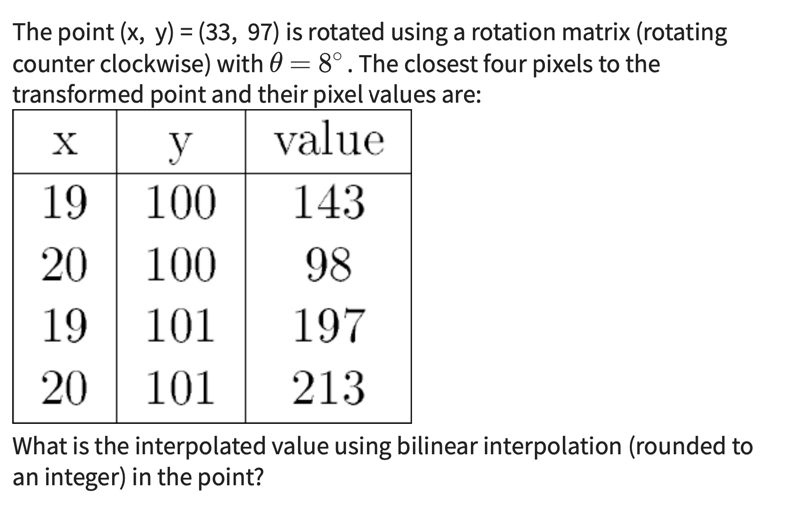

close all; clear; clc; ex = exam_funcs;

point= [33;97];

x = [19,20,19,20];
y = [100,100,101,101];
v = [143,98,197,213];

theta = 8; 

nI = ex.rotate2d(point,theta);

ex.BilinearInterpolation(nI,x,y,v)

ans =         177.06


Answer = 177

## Exercise 5

close all; clear; clc; ex = exam_funcs;
%Real world scenario:
g=20;
v = 28;
G = tand(v/2)*20;
hele_G = G*2

hele_G =           9.97



%Det tager fuglen 2 sek at flyve 10 m. Dvs fuglen flyver 5m/s. 


Answer = 

## Exercise 6 - meanfilter

close all; clear; clc; ex = exam_funcs;
legocar = imread('/Users/gabriellakierulff/Desktop/KID6SEM/Billedeanalyse/testdata/legocar.png');

%I_filt = ex.Filter(legocar,'median',10);


%Mean filter
fsize = 10;
h = ones(fsize)/fsize^2;
% Odd filter size ensures the kernel can be centered around one pixel
meanim = imfilter(legocar, h);

I_thres = (meanim>200);

I_blob = bwconncomp(I_thres);

stats = regionprops(I_blob)

stats = 5×1 struct array with fields:
    Area
    Centroid
    BoundingBox



%number of blobs = number of fields

Answer = 5

## Exercise 7

close all; clear; clc; ex = exam_funcs;
load('/Users/gabriellakierulff/Desktop/KID6SEM/Billedeanalyse/testdata/movingPoints.mat');
load('/Users/gabriellakierulff/Desktop/KID6SEM/Billedeanalyse/testdata/fixedPoints.mat')
mytform = fitgeotrans(movingpoints, fixedpoints,'NonreflectiveSimilarity');

forward = transformPointsForward(mytform,movingpoints);
forward()

ans =         628.89        303.02
        551.94        209.39
        488.91        177.51
        417.09        149.56
        444.52        209.62
        500.42        241.04
        356.80        217.55
        237.07        195.15
        335.33        261.61
        386.23        293.62


Answer = (6.28,303.02)

## Exercise 8

close all; clear; clc; ex = exam_funcs;

Answer = 

## Exercise 9

close all; clear; clc; ex = exam_funcs;

Answer = 

## Exercise 10

close all; clear; clc; ex = exam_funcs;

Answer = 

## Exercise 11

close all; clear; clc; ex = exam_funcs;

Answer = 

## Exercise 12

close all; clear; clc; ex = exam_funcs;

Answer = 

## Exercise 13

close all; clear; clc; ex = exam_funcs;

Answer = 

## Exercise 14

close all; clear; clc; ex = exam_funcs;

Answer = 

## Exercise 15

close all; clear; clc; ex = exam_funcs;

Answer = 

## Exercise 16

close all; clear; clc; ex = exam_funcs;

Answer = 

## Exercise 17

close all; clear; clc; ex = exam_funcs;

Answer = 

## Exercise 18

close all; clear; clc; ex = exam_funcs;

Answer = 

## Exercise 19

close all; clear; clc; ex = exam_funcs;

Answer = 

## Exercise 20

close all; clear; clc; ex = exam_funcs;

Answer = 

## Exercise 21

close all; clear; clc; ex = exam_funcs;

Answer = 

## Exercise 22

close all; clear; clc; ex = exam_funcs;

Answer = 

## Exercise 23

close all; clear; clc; ex = exam_funcs;

Answer = 

## Exercise 24

close all; clear; clc; ex = exam_funcs;

Answer = 

## Exercise 25

close all; clear; clc; ex = exam_funcs;

Answer = 